sequence = input("Enter sequence:-")

sequence =      2     1     2     1


N = [0 : length(sequence)-1]

N =      0     1     2     3


N1 = N + 1

N1 =      1     2     3     4


w = 2*pi*N1/length(sequence)

w =     1.5708    3.1416    4.7124    6.2832


DTFT = zeros(1, length(sequence))

DTFT =      0     0     0     0


for i=1:length(sequence)
    DTFT(i) = sum(sequence.*exp(-1*j*w(i)*N1))
end

DTFT = 1.0e-15 *

  -0.2220 + 0.2449i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


DTFT =   -0.0000 + 0.0000i  -2.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


DTFT =   -0.0000 + 0.0000i  -2.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


DTFT =   -0.0000 + 0.0000i  -2.0000 - 0.0000i   0.0000 + 0.0000i   6.0000 + 0.0000i


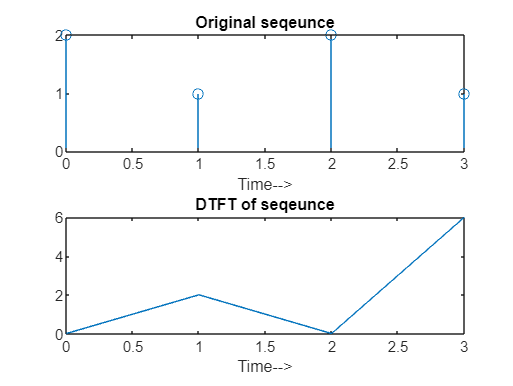

subplot(2,1,1)
stem(N,sequence)
xlabel('Time-->')
title('Original seqeunce')
subplot(2,1,2)
plot(N,abs(DTFT))
xlabel('Time-->')
title('DTFT of seqeunce')